# MATLAB Tutorial 4. Root Locus

## 1. 근궤적 그리기

### 1.1 실수 극점만 있는 경우

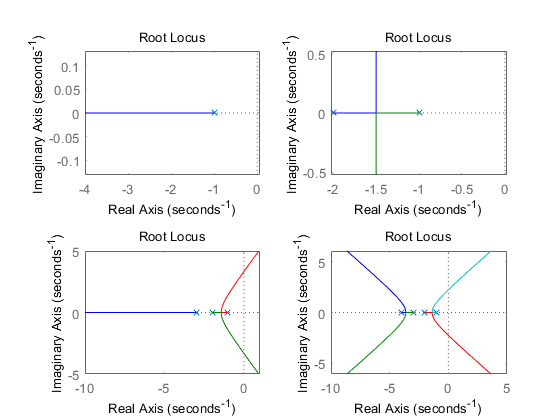

clc; clear
s = tf('s');
sys1 = 1/(s+1);
sys2 = 1/((s+1)*(s+2));
sys3 = 1/((s+1)*(s+2)*(s+3));
sys4 = 1/((s+1)*(s+2)*(s+3)*(s+4));

% figure(1)
% set(gcf,'Position',[100 300 700 500])
subplot(2,2,1)
rlocus(sys1)
subplot(2,2,2)
rlocus(sys2)
subplot(2,2,3)
rlocus(sys3)
subplot(2,2,4)
rlocus(sys4)

### 1.2 중극점, 복소극점

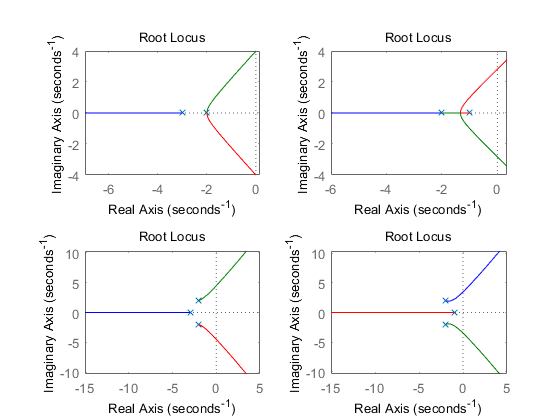

clc; clear; close all
s = tf('s');
sys1 = 1/((s+3)*(s^2+4*s+4));
sys2 = 1/((s+1)*(s^2+4*s+4));
sys3 = 1/((s+3)*(s^2+4*s+8));
sys4 = 1/((s+1)*(s^2+4*s+8));

subplot(2,2,1)
rlocus(sys1)
subplot(2,2,2)
rlocus(sys2)
subplot(2,2,3)
rlocus(sys3)
subplot(2,2,4)
rlocus(sys4)

### 1.3 영점 추가

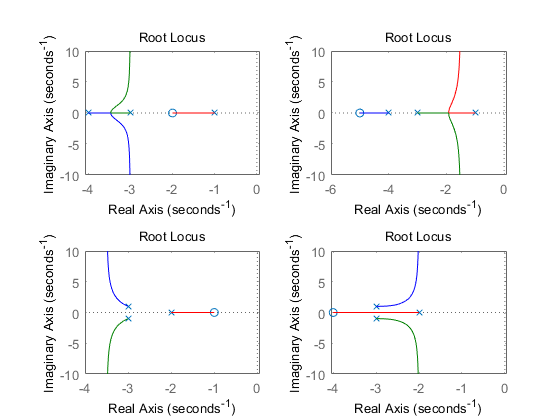

clc; clear; close all
s = tf('s');
sys1 = (s+2)/((s+1)*(s+3)*(s+4));
sys2 = (s+5)/((s+1)*(s+3)*(s+4));
sys3 = (s+1)/((s+2)*(s^2+6*s+10));
sys4 = (s+4)/((s+2)*(s^2+6*s+10));

subplot(2,2,1)
rlocus(sys1)
subplot(2,2,2)
rlocus(sys2)
subplot(2,2,3)
rlocus(sys3)
subplot(2,2,4)
rlocus(sys4)

### 1.4 기타 다양한 케이스들

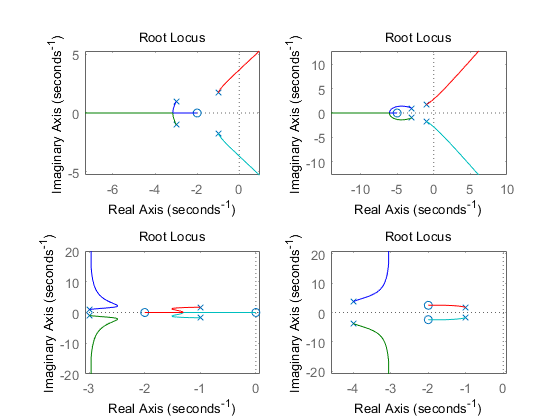

clc; clear; close all
s = tf('s');
sys1 = (s+2)/((s^2+2*s+4)*(s^2+6*s+10));
sys2 = (s+5)/((s^2+2*s+4)*(s^2+6*s+10));
sys3 = s*(s+2)/((s^2+2*s+4)*(s^2+6*s+10));
sys4 = (s^2+4*s+10)/((s^2+2*s+4)*(s^2+8*s+30));

subplot(2,2,1)
rlocus(sys1)
subplot(2,2,2)
rlocus(sys2)
subplot(2,2,3)
rlocus(sys3)
subplot(2,2,4)
rlocus(sys4)

## 2. 근궤적을 이용한 제어기 설계

다음과 같은 시스템이 있을 때 아래 조건을 만족하는 제어기의 상수 이득 K 값의 범위를 구하여라.

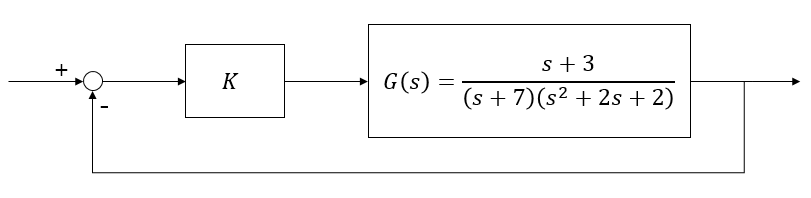

- 첨두시간: 1.5초 이하

- 최대초과: 20% 이하

- 정착시간: 3.5초 이하

이를 풀기 위해서는 먼저 시스템의 조건을 2차 표준시스템의 제동비($\zeta$)와 고유주파수($\omega_n$)에 대한 조건으로 바꿔야 한다.  s-plane에서 근궤적과 조건이 나타내는 범위를 선으로 표시한 후 조건을 만족하는 범위의 근궤적을 클릭하여 그 점에서의 상수 이득 값과 극점의 값을 확인한다. 

### 2.1 근궤적과 성능한계선 그리기

clc; clear; close all
% system with 3 poles and 1 zero
s = tf('s');
sys = (s+3)/((s+7)*(s^2+2*s+2));

% figure(1)
rlocus(sys)
hold on
axis([-10 2 -6 6])
% set(gcf,'Position',[100 100 800 800])

tp = 1.5;   % 첨두시간 1.5초 이하
Mp = 0.2;   % overshoot 20% 이하
ts = 3.5;   % 정착시간 3.5초 이하

% pi/wd < tp  ->  wd > pi/tp
wd_tp = pi/tp

wd_tp = 2.0944

% exp(-zeta*pi / sqrt(1-zeta^2)) < Mp
% ->  zeta^2 > (lnM)^2 / ((lnM)^2 + pi^2)
zeta_Mp = abs(log(Mp) / sqrt(log(Mp)^2 + pi^2))

zeta_Mp = 0.4559

theta_Mp = asin(zeta_Mp)

theta_Mp = 0.4734

% 4/sig < ts  ->  sig > 4/ts
sig_ts = 4/ts

sig_ts = 1.1429

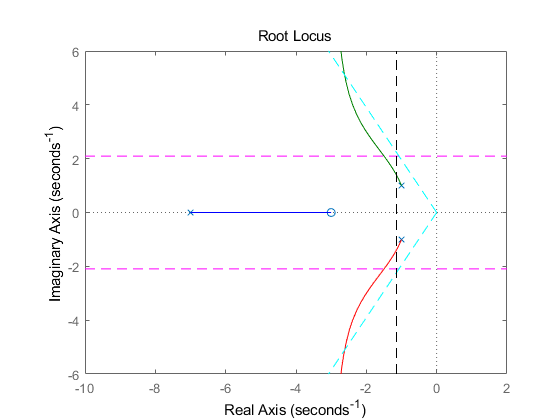

% line s=jwd_tp
plot([-100, 100], [wd_tp, wd_tp], 'm--')
plot([-100, 100], [-wd_tp, -wd_tp], 'm--')

% line with angle theta_Mp from imaginary axis
plot([0 -100*sin(theta_Mp)], [0  100*cos(theta_Mp)], 'c--')
plot([0 -100*sin(theta_Mp)], [0 -100*cos(theta_Mp)], 'c--')

% line s=-sig_ts
plot([-sig_ts, -sig_ts], [-100, 100], 'k--')
hold off

### 2.2 근궤적에서 유효 범위 구하기

근궤적을 확대하여 유효한 범위의 시작점과 끝점을 클릭하면 조건을 만족하는 K값의 범위와 그때의 극점 위치도 알 수 있다.

- 조건을 만족하는 최소 K=4.18, s=-1.23+j1.59

- 조건을 만족하는 최대 K=36.7, s=-2.62+j5.11